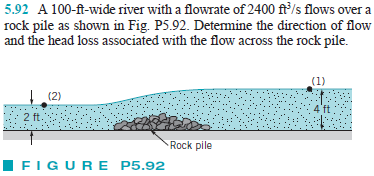

# given

u = symunit;
w = 100*u.ft;
Q = 2400*u.ft^3/u.s;
rho = 1.94*u.slug/u.ft^3;
gamma = 62.4*u.lbf/u.ft^3;
g = 32.2*u.ft/u.s^2;

# inflow properties

p1 = 0;
z1 = 4*u.ft;
A1 = w*z1;
V1 = Q/A1;

# outflow properties

p2 = 0;
z2 = 2*u.ft;
A2 = w*z2;
V2 = Q/A2;

# conservation of energy

syms hL;
hL = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1-hL);
hL_vpa = vpa(hL, 3) %#ok

$$hL\_vpa = 0.323\,\mathrm{ft}$$

clear hL_vpa;